# ENGR105    ---    Problem Set 3    ---   Arrays, Equations, and Functions

## Due: Friday, 9/18/2020

## Name:

#### The University of Pennsylvania code of academic integrity can be found here:

[https://catalog.upenn.edu/pennbook/code-of-academic-integrity/](https://catalog.upenn.edu/pennbook/code-of-academic-integrity/)

By submitting this assignment, you certify that you completed this assignment in compliance with the code of academic integrity, as defined above, and that the work here is your own. Collaboration is allowed and encouraged but  it is in your own best interest to be able to complete all the problems on your own. Collaboration is allowed, COPYING is NOT. Be sure you are able to reason through each step. 

#### Notes on HW submission:

- Please save the final document In the following format: "<your last name>_<your first name>_HW3.mlx

- Run the entire document (`f5`) prior to submitting. Following this, please **export to .pdf** and **submit both** the .mlx file and the .pdf file to Canvas.

- The LiveScript file may be exported to PDF using the **Save** dropdown menu.

- If it is not selected by default, select "Output Inline" at the top right of the LiveScript document to display the output below your code (rather than to the right).

#### Purpose of this problem set:

- Develop familiarity defining and manipulating vectors and matrices.

- Practice converting a word problem into a computational strategy for solving it.

- Use matrix-based approaches to solve systems of linear equations.

- Practice creating new functions.

#### Notes about MATLAB LiveScripts:

- The gray regions are "code" regions. Entering and running your code here is the same as running it in a `.m` script file or on the command line.

- "Running a piece of code" means you are executing the code in that section only. **Press **`Cntl`** + **`Enter`** to run a given section.**

- Press `f5` to run all sections of the document.

- To remove inline figures, right click and select "Clear All Output."

- When you run a section (each section refers to a different problem or part of a problem), all variables and vectors are stored in MATLAB and may be called from the command line.

**Reminder: Prior to submitting, be sure to run ****all**** sections of the document to ensure that it works properly. After running all sections, export the document to pdf.**

## PROBLEM 1 (20 pts): Array operations, pt. 1

Consider the arrays $A$, $B$, and $C$, defined here.

        
$$A=\left\lbrack \begin{array}{cccc}
1 & 5 & 7 & 9
\end{array}\right\rbrack$$
        
$$B=\left\lbrack \begin{array}{c}
2\\
5\\
6\\
7
\end{array}\right\rbrack$$
        
$$C=\left\lbrack \begin{array}{ccc}
11 & 14 & 17\\
12 & 15 & 18\\
13 & 16 & 19
\end{array}\right\rbrack$$


**a)** Generate MATLAB code to produce each of these arrays.

A = [1,5,7,9]

A =      1     5     7     9


B = [2;5;6;7]

B =      2
     5
     6
     7


C = [11,14,17;12,15,18;13,16,19]

C =     11    14    17
    12    15    18
    13    16    19


**b) **Using array $A$, $B$, or $C$ -- and **only** the colon operator (`:`), the transpose (`'`), and indexing as necessary-- produce each of the following arrays in a single expression.

***i)***  $D=\left\lbrack \begin{array}{ccc}
12 & 15 & 18\\
13 & 16 & 19
\end{array}\right\rbrack$

D = C(2:3,:)

D =     12    15    18
    13    16    19


***ii)***  $E=\left\lbrack \begin{array}{cc}
17 & 11\\
18 & 12\\
19 & 13
\end{array}\right\rbrack$

E = [C(:,3),C(:,1)]

E =     17    11
    18    12
    19    13


***iii)***  $F=\left\lbrack \begin{array}{c}
1\\
5
\end{array}\right\rbrack$

F = A(1:2)'

f =      1
     5


***iv)***  $G=\left\lbrack \begin{array}{ccccc}
13 & 14 & 15 & 16 & 17
\end{array}\right\rbrack$

G = [C(3,1), C(:,2)', C(1,3)]

G =     13    14    15    16    17


***v)***  $X=\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 11 & 17\\
0 & 13 & 19
\end{array}\right\rbrack$

X(2:3,2:3) = [C(1,[1,3]); C(3,[1,3])]

X =      0     0     0
     0    11    17
     0    13    19


***vi)***  $Y=\left\lbrack \begin{array}{ccccc}
11 & 0 & 12 & 0 & 13\\
0 & 0 & 0 & 0 & 0\\
14 & 0 & 15 & 0 & 16\\
0 & 0 & 0 & 0 & 0\\
17 & 0 & 18 & 0 & 19
\end{array}\right\rbrack$

Y((1:2:5),(1:2:5)) = C'

Y =     11     0    12     0    13
     0     0     0     0     0
    14     0    15     0    16
     0     0     0     0     0
    17     0    18     0    19


## PROBLEM 2 (20 pts): Systems of linear equations

Solve each of the following systems of linear equations.** After each part, please do not suppress your code in this section and explicitly write out the value of each variable.**

**a) **

                
$$\begin{array}{l}
z=1\;-x-2y\\
z=-2\;-x+4y\\
z=3\;-2x-y
\end{array}$$


%first creating a a set of empty variables in order to go into the vecvtor
%array of x1

x = 0;
y = 0;
z = 0;

A = [-1, -2, -1;
     -1, 4, -1;
     -2, -1, -1]

A =     -1    -2    -1
    -1     4    -1
    -2    -1    -1


b=[-1;2;-3]

b =     -1
     2
    -3


v = [x,y,z]

v =      0     0     0


v = A\b

v =     2.5000
    0.5000
   -2.5000


%Showing what each variable would end up eqia;omg
x = v(1)

x = 2.5000

y = v(2)

y = 0.5000

z = v(3)

z = -2.5000

**b)**

                
$$\begin{array}{l}
{-x}_1 +x_3 +{2x}_4 +{3x}_5 -1=0\\
x_1 +{2x}_2 +{3x}_3 +{4x}_4 -2=0\\
x_1 +{2x}_2 +{3x}_3 -x_4 =3\\
{2x}_1 +{3x}_2 -x_3 +x_5 -4=0\\
{3x}_1 -x_2 +x_4 +{2x}_5 =5
\end{array}$$


x1 = 0

x1 = 0

x2 = 0

x2 = 0

x3 = 0

x3 = 0

x4 = 0

x4 = 0

x5 = 0

x5 = 0


A = [-1, 0, 1, 2, 3;
     1, 2, 3, 4, 0;
     1, 2, 3, -1, 0;
     2, 3, -1, 0, 1;
     3, -1, 0, 1, 2];
 x = [x1;x2;x3;x4;x5]

x =      0
     0
     0
     0
     0


 b = [1;2;3;4;5]

b =      1
     2
     3
     4
     5


 
 x = A\b

x =     1.3000
    0.3000
    0.3000
   -0.2000
    0.8000


 x1 = x(1)

x1 = 1.3000

 x2 = x(2)

x2 = 0.3000

 x3 = x(3)

x3 = 0.3000

 x4 = x(4)

x4 = -0.2000

 x5 = x(5)

x5 = 0.8000

## PROBLEM 3 (10 pts): Converting a word problem into a numerical solution

As an engineer, you will use your knowledge of engineering to convert real-world problems into (hopefully solvable) mathematical problems. You will then use your mathematical knowledge (and skills with scientific computing!) to solve them. The purpose of this problem is to work through this process with a non-engineering problem, solving the problem with the matrix representation approach.

**Prompt:**

*Every week, Mike consumes *$a$* lentil burgers, *$b$* pieces of grilled chicken, and *$c$* mugs of coffee (don't worry, I eat other things too). Each lentil burger is made from 1/4 cup of lentils, each piece of chicken is 4 ounces (1/4 lb), and 2 tablespoons of coffee grounds (1/8 cup) produce one 1 mug of coffee. *

*However, Mike buys all of the required ingredients from a different location each week, often because of convenience:*

- *At FroGro (before it closed), lentils were ****$2/cup****, chicken was ****$4/lb****, and coffee grounds were ****$1/cup****. Mike would spend ****$7.25**** on these ingredients when shopping at FroGro. *

- *At Supremo shop n bag, lentils are ****$1/cup****, chicken is ****$3/lb****, and coffee grounds were ****$2/cup****. Mike spends**** $6.25**** on these ingredients when shopping at Supremo. *

- *At Aldi, lentils are ****$1/cup****, chicken is ****$3/lb****, and coffee grounds were ****$1/cup****. Mike spends $5 on these ingredients when shopping at Aldi. *

*If Mike consumes the same amount of lentil burgers, grilled chicken, and coffee every week -- and assuming he eats all of the meals he prepares -- how many lentil burgers, pieces of chicken, and mugs of coffee does he consume? ***To solve this problem, use what you know about matrices and systems of linear equations.**

**a) **Convert the above word problem into a **system of linear equations**. Insert your system of equations in the space provided below.

            
$$\begin{array}{l}
\frac{2}{4}a+\frac{4}{4}b+\frac{1}{8}c=\;7\ldotp 25\\
\frac{a}{4}+\frac{3}{4}b+\frac{2}{8}c=6\ldotp 25\\
\frac{a}{4}+\frac{3}{4}b+\frac{1}{8}c=5
\end{array}$$


**b)** Convert your system of linear equations into matrix representation.** Be sure to add comments** to ensure that your code is clear.


 A = [.5 ,1 ,.125;
     .25, .75, .25; 
     .25, .75, .125]

b1 = [7.25;6.25;5]
a = 0;
b = 0;
c = 0;

x = [a,b,c]

x =      0     0     0


**c) **Solve the system using matrix division:

x = A\b1

x =      6
     3
    10


a = x(1)
b = x(2)
c = x(3)

PS: converting between American standard units annoys me too.

## PROBLEM 4 (25 pts): Law of Cosines

The Law of Cosines relates the lengths of the sides of a triangle to the cosine of the angle "opposite from side c," which is described in the following equation and diagram

                            
$$c^2 =a^2 +b^2 -2\;a\;b\;\cos \left(\gamma \right)$$


                    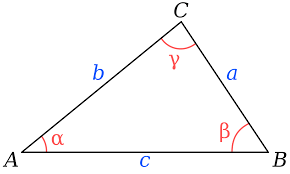

**a) Write a MATLAB function** named `lawOfCos` (in the space provided at the end of this LiveScript document) that uses the law of cosines to compute the angle $\gamma$ based on an input of the side lengths of the triangle. It should calculate the angle opposite of side $c$, as defined above.

**Your function should have the following characteristics:**

- It should have the correct name, defined above.

- The output should be **one scalar** value, with units of **degrees**.

- The input should be **one **`(1x3)`** vector** containing the lengths of all sides of the triangle.

- The input vector should be read inside the function as $\left\lbrack \begin{array}{ccc}
a & b & c
\end{array}\right\rbrack$, where $a$ represents the length of side $a$, $b$ represents the length of side $b$, and $c$ represents the length of side $c$. **That is, your function should calculate the angle assuming the last entry in the input vector corresponds to side **$c$.

- As with all custom functions, it should be well commented.

**Create this function in the space provided at the end of this LiveScript file.**

**b) **Using your function, calculate the angle $\gamma$ when $a=3,b=3,\textrm{and}\;c=3$ and assign the output to a new variable `hw3_b`. Do not supress the output of your code in **b)** with a semicolon (`;`). 

v = [3,3,3]

v =      3     3     3


hw3_b = lawofCosine(v)

hw3_b = 60.0000

**c)** Using your function, calculate the angle $\gamma$ when $a=4,b=3,\textrm{and}\;c=2$ and assign the output to a new variable `hw3_c`. Do not supress the output of your code in **c)** with a semicolon (`;`). 

v = [4,3,2]

v =      4     3     2


hw2_c = lawofCosine(v)

hw2_c = 28.9550

## PROBLEM 5 (25 pts): Mathematical roulettes

If you have ever played with a spirograph toy (see wikipedia for .gifs), you have produced shapes known as hypocycloids, epicycloids, epitrochoids and hypotrochoids. All of these shapes can be produced when a circle rotates about another circle. In this problem, you will produce MATLAB code to produce these shapes.

**a)** **Create a MATLAB function **called `spirograph` (in the space provided at the end of this LiveScript document) that takes in **three scalar inputs** `R`, `r`, and `d`. Your function should create a curve of the following form.

        
$$x\left(\theta \right)=\left(R+r\right)\;\cos \theta +d\;\cos \left(\left(\frac{R+r}{r}\right)\theta \right)$$


        
$$y\left(\theta \right)=\left(R+r\right)\;\sin \theta -d\;\sin \left(\left(\frac{R+r}{r}\right)\theta \right)$$


Create the geometric shape using the `plot()` command. **Be sure your plot displays a line** (rather than points).

**Hint 1**: the only thing your function should "output" is a plot of the curve corresponding to the inputs `R`, `r`, and `d`

**Hint 2**: you should begin by creating a vector called `theta` that has values between 0 and 10$\pi$ in steps of no more than 0.001 radians. Then compute values for `x` and `y` using array operations, addition, subtraction, the cosine function, etc. This should all be achieved without loops. 

**b)** Using your function, produce the shape corresponding to `R= 10, r = 4, d = 4`.

theta =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


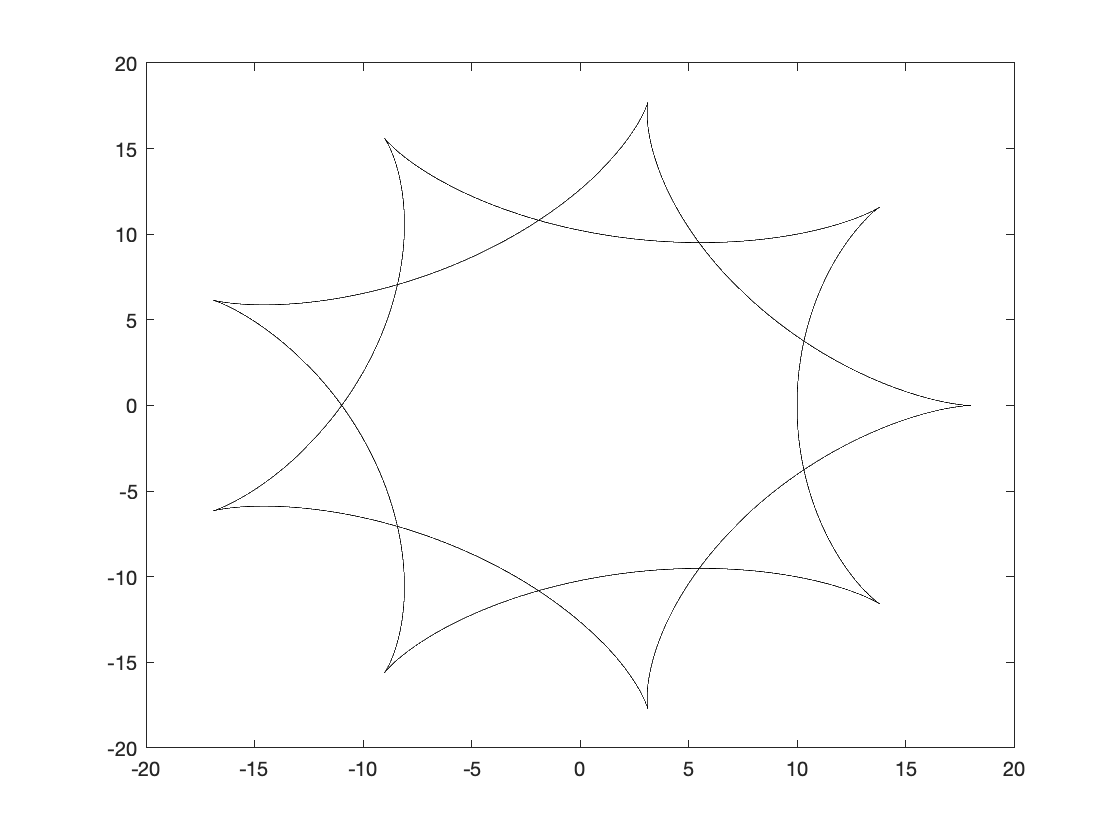

spirograph(10,4,4);

**c)** Using your function, produce the shape corresponding to `R= 12, r = -1, d = 2.5`.

theta =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


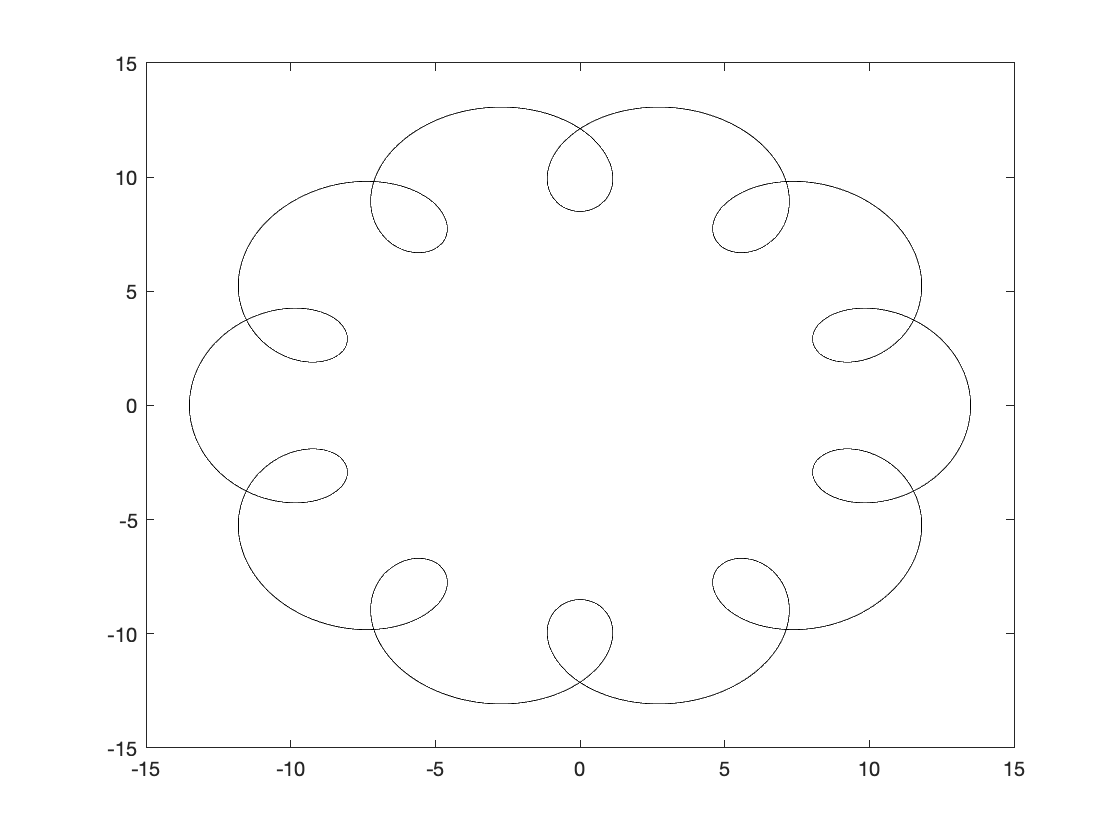

spirograph(12,-1,2.5);

**d)** Using your function, produce the shape corresponding to `R= -20, r = 30, d = 10`.

theta =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


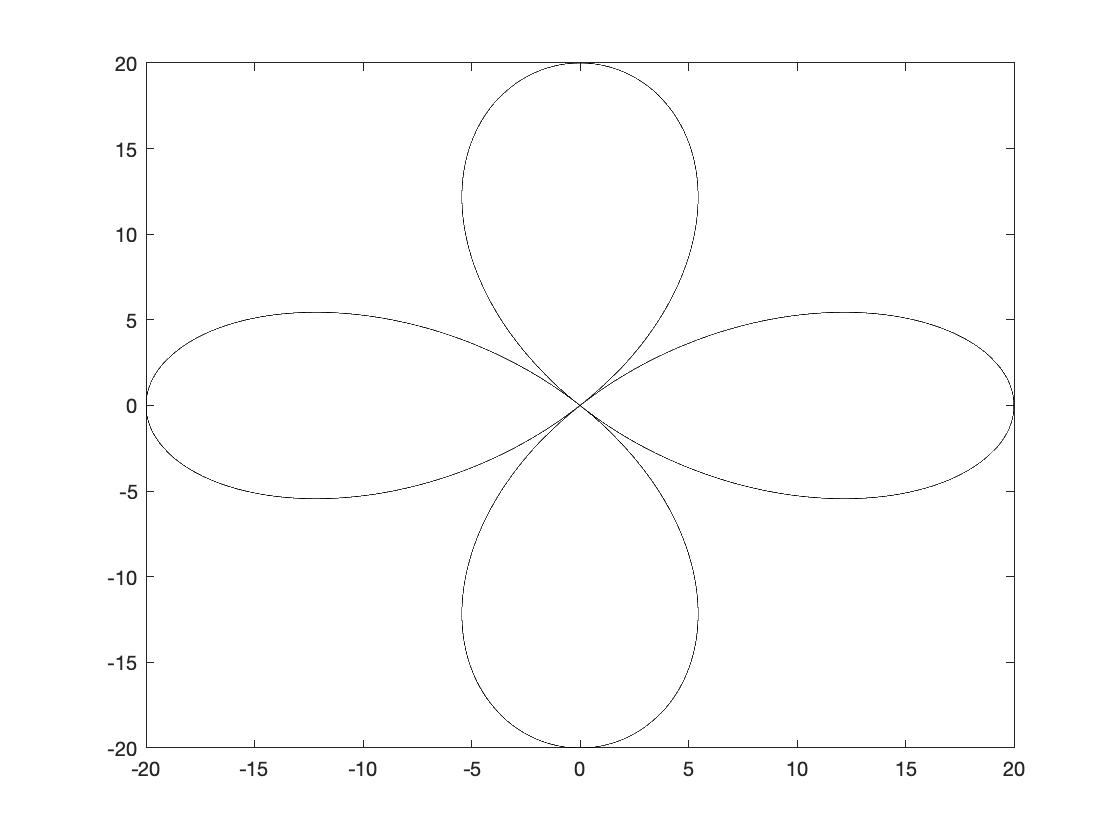

spirograph(-20,30,10);

## Problems Set 3: functions stored below

**Use the space below for PROBLEM 4.**

function gamma = lawofCosine(v) 
    %law of cosine is c^2 = a^2+b^2-2abcos(gamma)
   
    gamma = acosd((v(1)^2+v(2)^2-v(3)^2)/(2*v(1)*v(2)));
end


**Use the space below for PROBLEM 5.**

%theta = 0:0.001:10*pi

function spirograph(R, r, d)
    theta = 0:0.001:10*pi;
    x = (R+r).*cos(theta) + d*cos(((R+r)/r).*theta);
    y = (R+r).*sin(theta) - d*sin(((R+r)/r).*theta);
    plot(x,y,"k-")
end
